% clear; close all;

% Load data from MAT-file into workspace 
test_timeseries = load("angles10.mat")

test_timeseries = struct with fields:
    ans: [7×17501 double]


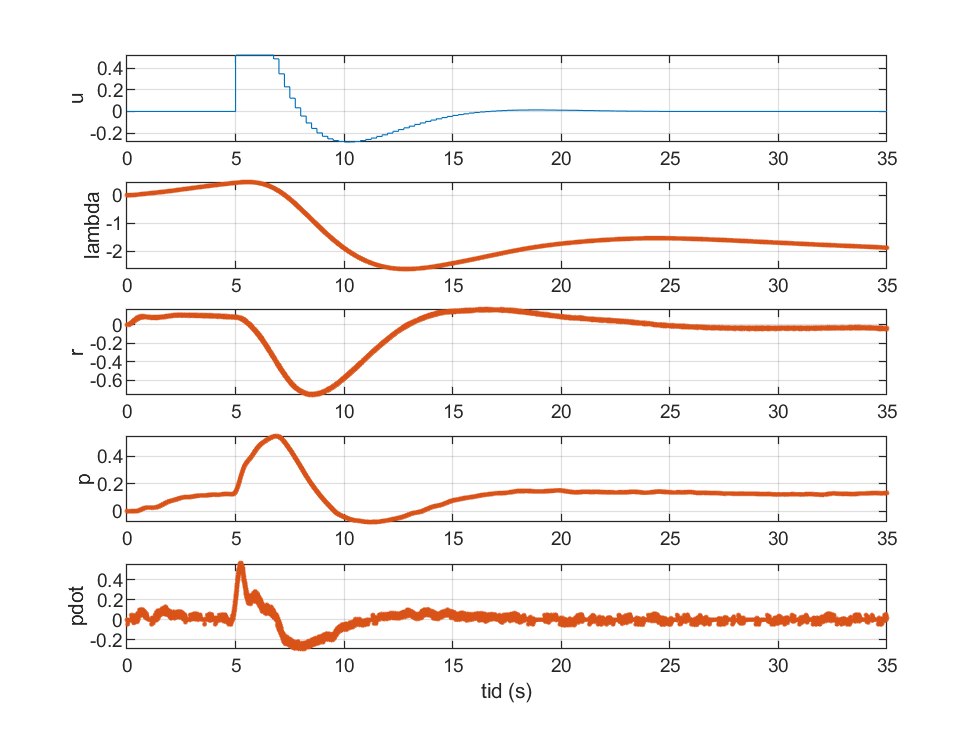

sim_data = test_timeseries.ans;

simTime = sim_data(1, :);
% uTime = uref.Data;
x1sim = sim_data(2, :); % lambda
x2sim = sim_data(3, :); % r
x3sim = sim_data(4, :); % p
x4sim = sim_data(5, :); % p_dot

% elevation = sim_data(6, :);
% elevation_rate = sim_data(7, :);

% % Setup gca 
% figure(); grid on; hold on
% % set(gca,'YAxisLocation','right')
% axis padded

% Plot data
% plot(time, travel,"linewidth", 1,"linestyle", ".");
% plot(time, pitch,"linewidth", 1,"linestyle", ".");

% Set title, labels and legends
% title("Testing loading data for plotting", "Interpreter", "latex", 'fontweight','bold', "FontSize", 14)
% legend(["Travel" "Elevation"], "Location", "best", "Interpreter", "latex")
% xlabel("Time $t$ (s)","Interpreter","latex")
% ylabel("Radians" , "Interpreter","latex")

figure(2)
subplot(511)
stairs(t,u),grid
ylabel('u')
subplot(512)
plot(simTime,x1sim,'m',simTime,x1sim, '.'),grid
ylabel('lambda')
subplot(513)
plot(simTime,x2sim,'m',simTime,x2sim', '.'),grid
ylabel('r')
subplot(514)
plot(simTime,x3sim,'m',simTime,x3sim, '.'),grid
ylabel('p')
subplot(515)
plot(simTime,x4sim,'m',simTime,x4sim','.'),grid
xlabel('tid (s)'),ylabel('pdot')


saveas(gcf, "simP_10.eps", "-depsc")

Error using saveas (line 179)
Unsupported format or extension: -depsc